syms x
s= tf([1 0],1);
%our transferfunctions
Blank=1; %To clear the control designer app
G=tf([-116.8 0],[1 0.45 -83.11 -2.295]);%Our TF
xG = (-116.8*x)/(x^3+0.45*x^2-83.11*x-2.295)

$$xG = \frac{584\,x}{5\,\left(-x^{3}-\frac{9\,x^{2}}{20}+\frac{8311\,x}{100}+\frac{459}{200}\right)}$$


%Using PID control
%Setting up values
K=[-20 -110 -1.7]; %Gain matrix, kp ki kd
%setting up functions
N=1000;
P = K(1);
I = K(2)/s;
D= K(3)*s;
%D = K(3)*(N/(1+N*(1/s)));
%Setting up functions
PID = P+I+D

PID =
 
  -1.7 s^2 - 20 s - 110
  ---------------------
            s
 
Continuous-time transfer function.



PIDx = K(1) + K(2)/x + K(3)*x;

%calculating the steady state error of transferfunction 
%complimented with PID | very good ess-value. 
ess=1/round(abs(limit(PIDx*xG,x,0)))

$$ess = \frac{1}{5598}$$


%Open loop and closed loop
%Making step-response, root locus 
DT=series(G,PID);
CL=feedback(DT,1)

CL =
 
     198.6 s^3 + 2336 s^2 + 12848 s
  -------------------------------------
  s^4 + 199 s^3 + 2253 s^2 + 1.285e04 s
 
Continuous-time transfer function.



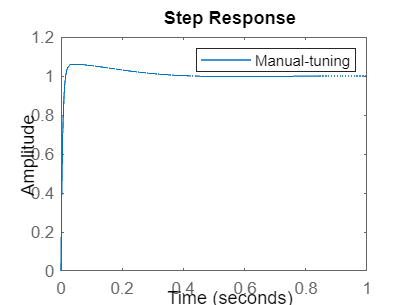

step(CL,1), legend('Manual-tuning')

stepinfo(CL)

ans = struct with fields:
         RiseTime: 0.0096
    TransientTime: 0.2527
     SettlingTime: 0.2527
      SettlingMin: 0.9072
      SettlingMax: 1.0603
        Overshoot: 6.0115
       Undershoot: 0
             Peak: 1.0603
         PeakTime: 0.0435


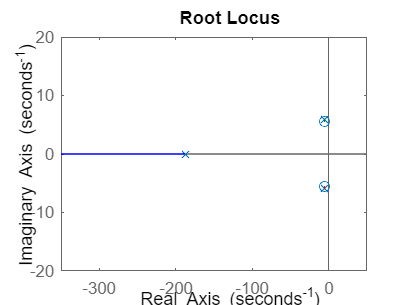

rlocus(CL)

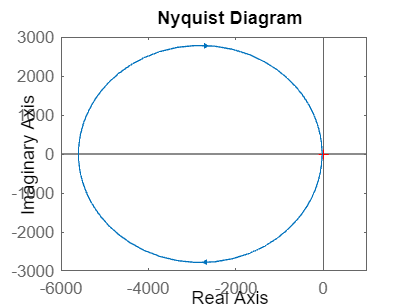

nyquistplot(G*PID)

%finding poles and zeores of closed loop
pole(CL),zero(CL)

ans = 1.0e+02 *

   0.0000 + 0.0000i
  -1.8735 + 0.0000i
  -0.0583 + 0.0588i
  -0.0583 - 0.0588i


ans =    0.0000 + 0.0000i
  -5.8824 + 5.4867i
  -5.8824 - 5.4867i




%discretisizing PID-controller
BW =bandwidth(CL)  %Bandwidth

BW = 208.6989

Wsamplemin = 20*BW

Wsamplemin = 4.1740e+03

Tsmax = 2*pi/Wsamplemin

Tsmax = 0.0015

dD=c2d(PID,0.005, 'tustin')

dD =
 
  -700.3 z^2 + 1359 z - 660.3
  ---------------------------
            z^2 - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[numerator, denominator]=tfdata(dD,'v') %poler

numerator = 1.0e+03 *

   -0.7003    1.3594   -0.6603


denominator =      1     0    -1



%Conclusion:
%PID controller gives a good response, whereas better values 
%are expected to be found if so decided upon. 
%Currently the PID will be implemented further and corrected if needed

%UPDATE:
%PID has been tested and works initially, but has overcorrection trouble
%and steers out of control as time goes on. 
%Controller for reference value has been used in the document:
%----------ReferenceController_UsingButterWorth.mlx----------

%UPDATE-2:
%In the following week (6/3-11/3), a decision to go further with PID
%or move on to cascade will be made.
%Free form at this time is not possible.
%For further info on free form check document:
%----------StabilizingRootLocus_UsingFreeForm_AlsoHasOldReportExample.mlx----------

%TO BE DONE:
%make document for cascade control, and for LQR-control (coupled with state-space model).